A =      2     0
     1    -1


twonorm =    2.2882e+00


onenorm =      3


ans =      3


infnorm =      2


ans =      2


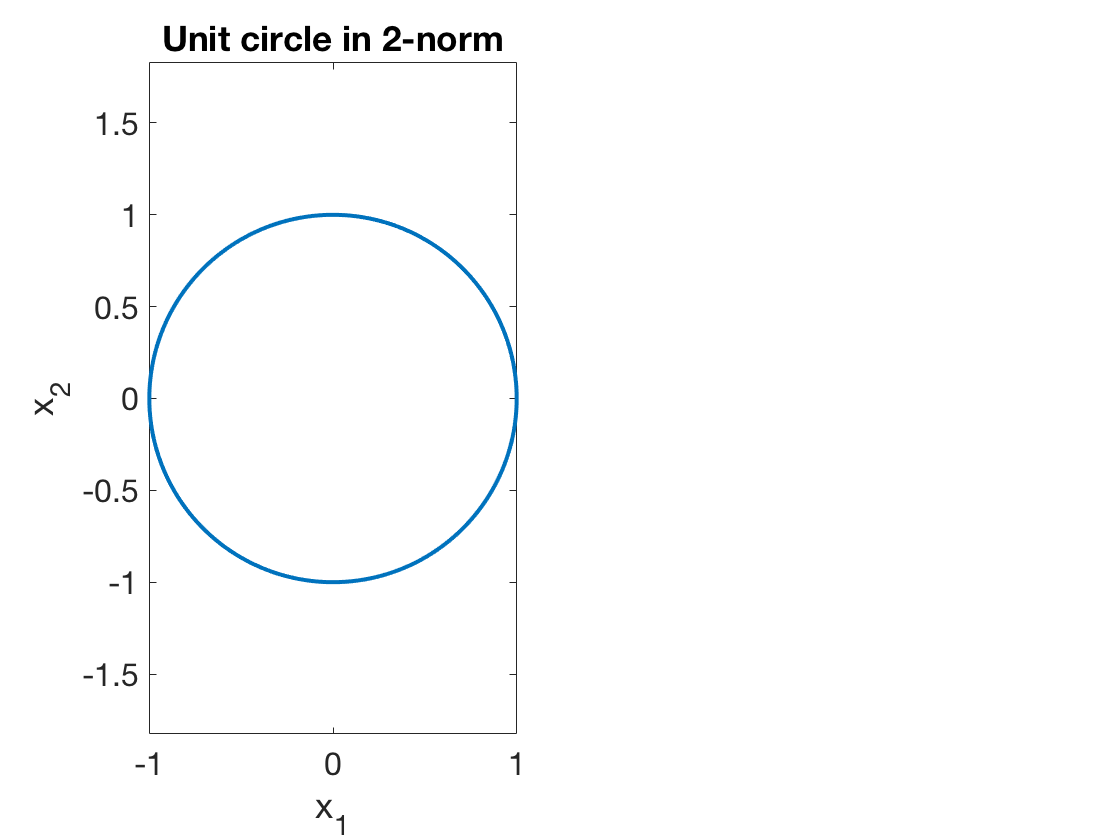

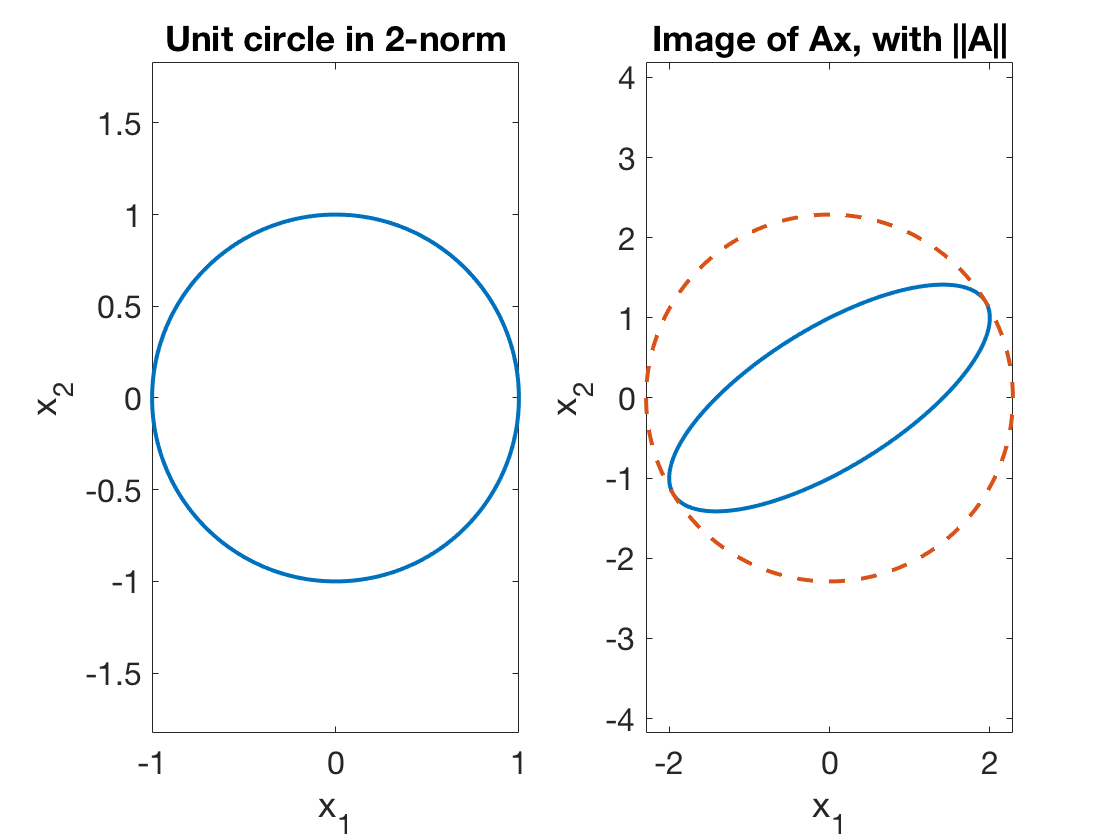

A = [ 2  0; 1  -1 ]

The default norm returned by the `norm` command is the 2-norm.

twonorm = norm(A)

You can get the 1-norm as well.

onenorm = norm(A,1)

The 1-norm is equivalent to 

max( sum(abs(A),1) )   % sum along rows (1st matrix dimension)

Similarly, we can get the $\infty$-norm and check our formula for it.

infnorm = norm(A,inf)
max( sum(abs(A),2) )   % sum along columns (2nd matrix dimension)

Here we illustrate the geometric interpretation of the 2-norm. First, we will sample a lot of vectors on the unit circle in $\mathbf{R}^2$. 

theta = linspace(0,2*pi,601);
x = [ cos(theta); sin(theta) ];  % 601 unit columns
subplot(1,2,1), plot(x(1,:),x(2,:)), axis equal
title('Unit circle in 2-norm')
xlabel('x_1'),  ylabel('x_2')

We can apply $\mathbf{A}$ to every column of $\mathbf{x}$ simply by using

Ax = A*x;

We superimpose the image of the unit circle with the circle whose radius is $\|\mathbf{A}\|_2$, and display multiple plots with the `subplot` command.

subplot(1,2,2), plot(Ax(1,:),Ax(2,:)), axis equal
hold on, plot(twonorm*x(1,:),twonorm*x(2,:),'--')
title('Image of Ax, with ||A||')
xlabel('x_1'),  ylabel('x_2')